clear

## Task1

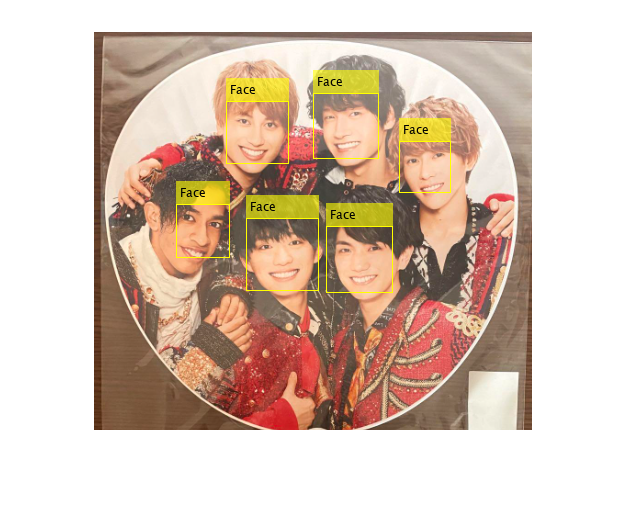

% face
faceDetector = vision.CascadeObjectDetector;
I = imread('face3.png');
bboxes = faceDetector(I);
IFaces = insertObjectAnnotation(I, 'rectangle', bboxes, 'Face');
imshow(IFaces)

## Task2

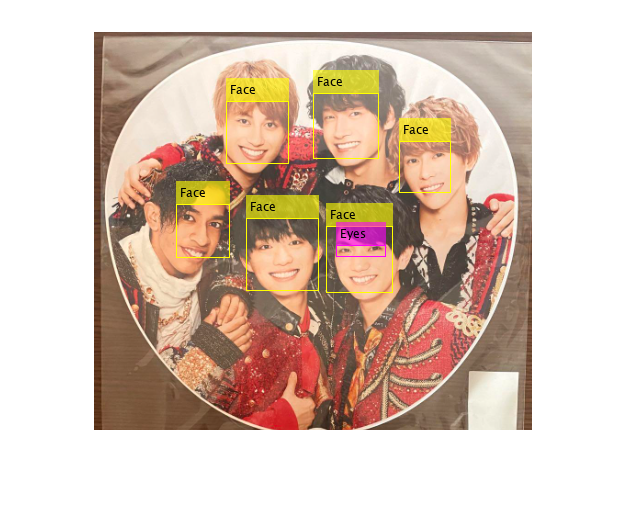

% eyes
eyesDetector = vision.CascadeObjectDetector('ClassificationModel', 'EyePairSmall', 'UseROI', true);
counter = 1;
for i = 1:1:length(bboxes)
    temp = eyesDetector(I, bboxes(i, :));
    if ~isempty(temp)
        bboxes2(counter, :) = temp;
        counter = counter + 1;
    end
end
IEyes = insertObjectAnnotation(IFaces, 'rectangle', bboxes2, 'Eyes', 'Color', 'magenta');
imshow(IEyes);

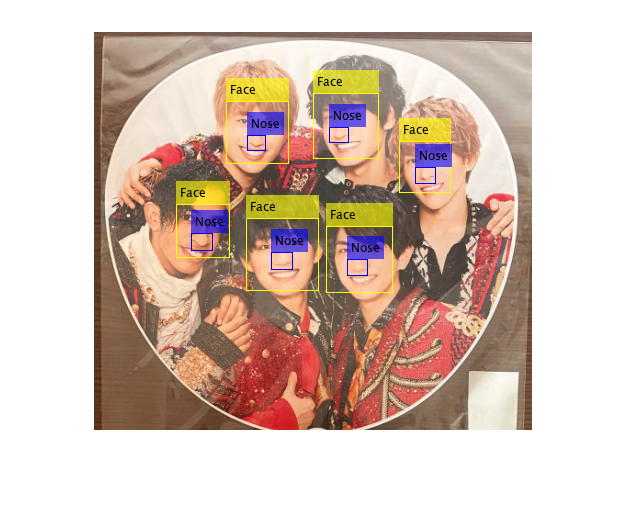


% nose
noseDetector = vision.CascadeObjectDetector('ClassificationModel', 'Nose', 'UseROI', true);
counter = 1;
for i = 1:1:length(bboxes)
    temp = noseDetector(I, bboxes(i, :));
    if ~isempty(temp)
        bboxes3(counter, :) = temp;
        counter = counter + 1;
    end
end
INose = insertObjectAnnotation(IFaces, 'rectangle', bboxes3, 'Nose', 'Color', 'blue');
imshow(INose);